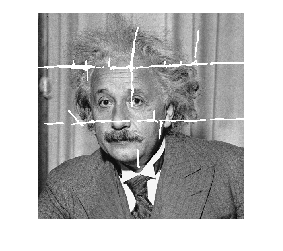

I=imread("EINSTEIN.tif");
g=im2gray(I);
[r c]=size(g);
t=[];

for i=1:1:r

    for j=1:1:c

        if g(i,j)==255
                 
          t(i,j)=0;

        else

           t(i,j)=255;

        end    

    end

end

bin_img=uint8(t);

imshow(I)

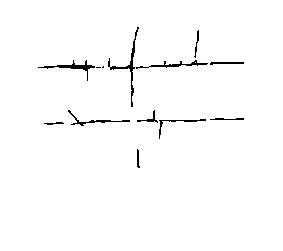


imshow(bin_img)

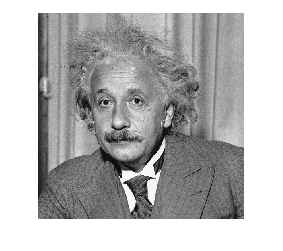


for i=1:1:r
    if g(i,1)==255
        g(i,1)=g(i-1,1);
    end
    if g(i,2)==255
        g(i,2)=g(i-1,2);
    end

    if g(i,c-1)==255
        g(i,c-1)=g(i-1,c-1);
    end
    if g(i,c)==255
        g(i,c)=g(i-1,c);
    end
end

for j=1:1:r
    if g(1,j)==255
        g(1,j)=g(1,j-1);
    end
    if g(2,j)==255
        g(2,j)=g(2,j-1);
    end
    if g(r-1,j)==255
        g(r-1,j)=g(r-1,j-1);
    end
    if g(r,j)==255
        g(r,j)=g(r,j-1);
    end
end

for i=1:1:r
    for j=1:1:c
        if g(i,j)==255
            p=i;
            q=j;
            q1=j;
            c1=0;
            c2=0;
            while g(p,q)==255
                c1=c1+1;
                q=q+1;
            end
            while g(p,q1)==255
                c2=c2+1;
                p=p+1;
            end

            if c1>c2
                if g(p+1,j)==255
                    g(p+1,j)=g(p,j);
                end
                x=[i-2 i-1 p p+1];
                y=[g(i-2,j) g(i-1,j) g(p,j) g(p+1,j)];
                xx=i-2:1:p+1;
                v=spline(double(x),double(y),xx);
                for c3=1:1:(p-i+1)
                    g(i-2+c3,j)=v(c3);
                end
                    
                
            end
            if c1<=c2
                if g(i,q+1)==255
                    g(i,q+1)=g(i-1,q+1);
                end
                x=[j-2 j-1 q q+1];
                y=[g(i,j-2) g(i,j-1) g(i,q) g(i,q+1)];
                xx=j-2:1:q+1;
                v=spline(double(x),double(y),xx);
                
                    for c4=1:1:(q-j+1)
                    g(i,j-2+c4)=v(c4);
                    end
                    
                
            end
        end

     end
end



imshow(g)



score1= brisque(g) 

score1 = 28.5211

score2= niqe(g)

score2 = 5.1401

score3= piqe(g) 

score3 = 41.5703